## divide train set and test set

data = X_noout;
label = y_noout;
format short g

nums = 35;
spa_svm_acctrains = []; 
spa_svm_acctests = [];
cs = [];
gs = [];

vsel_spa =     20   324   325   323   326   322   327   321   334   335   333   320   328   336   332   330   331   329   189   319   190   181   188   182   180   337   191   187   183   339   173   179   174   186   340


*.*
optimization finished, #iter = 226
nu = 0.050611
obj = -18.846048, rho = -0.087694
nSV = 71, nBSV = 0
*.*
optimization finished, #iter = 186
nu = 0.039096
obj = -14.558770, rho = 0.035702
nSV = 78, nBSV = 0
*.*
optimization finished, #iter = 172
nu = 0.031913
obj = -11.882471, rho = -0.154018
nSV = 63, nBSV = 0
*.*
optimization finished, #iter = 204
nu = 0.052075
obj = -19.727849, rho = 0.134575
nSV = 60, nBSV = 1
.*
optimization finished, #iter = 259
nu = 0.175318
obj = -77.912089, rho = -0.017310
nSV = 62, nBSV = 13
*
optimization finished, #iter = 165
nu = 0.035995
obj = -13.403733, rho = -0.197391
nSV = 62, nBSV = 0
Total nSV = 176
*.*
optimization finished, #iter = 221
nu = 0.043908
obj = -16.349986, rho = -0.134917
nSV = 71, nBSV = 0
*.*
optimization finished, #iter = 207
nu = 0.035367
obj = -13.170243, rho = -0.034510
nSV = 73, nBSV = 0
*.*
optimization finished, #iter = 172
nu = 0.032135
obj = -11.966153, rho = -0.208903
nSV = 62, nBSV = 0
*.*
optimization finished, #iter =

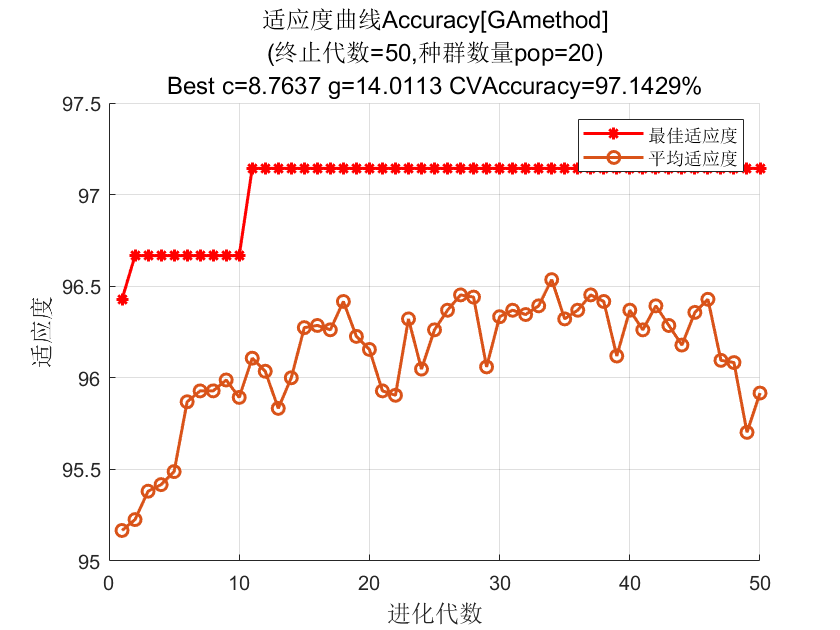

*
optimization finished, #iter = 194
nu = 0.023338
obj = -21.518855, rho = -0.148182
nSV = 38, nBSV = 1
*
optimization finished, #iter = 176
nu = 0.012359
obj = -11.373290, rho = 0.048215
nSV = 39, nBSV = 0
*
optimization finished, #iter = 104
nu = 0.014980
obj = -13.785744, rho = -0.125354
nSV = 28, nBSV = 0
*
optimization finished, #iter = 180
nu = 0.027451
obj = -27.927904, rho = 0.261349
nSV = 33, nBSV = 1
*.*
optimization finished, #iter = 309
nu = 0.162289
obj = -195.471822, rho = 0.174578
nSV = 53, nBSV = 22
*
optimization finished, #iter = 81
nu = 0.017308
obj = -15.925283, rho = -0.098587
nSV = 29, nBSV = 0
Total nSV = 135


Accuracy = 99.2857% (417/420) (classification)


Accuracy = 98.324% (176/179) (classification)


tic
for i = nums
    data_spa = data(training(cvp), :);
    [vsel_spa] = feature_spa(data_spa, 20, i)
    
    train_data  = data(training(cvp), vsel_spa);
    train_label = label(training(cvp));
    test_data   = data(test(cvp), vsel_spa);
    test_label  = label(test(cvp));
    
    [bestacc, bestc, bestg] = gaSVMcgForClass(train_label, train_data);
    
    s = 0;
    t = 2;
    c = bestc;
    g = bestg;
    options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
    model = libsvmtrain(train_label, train_data, options); 

    [train_pred_label, train_acc, ~]...
               = libsvmpredict(train_label, train_data, model);
    [test_pred_label, test_acc, ~]...
               = libsvmpredict(test_label, test_data, model);
    
    spa_svm_acctrains = [spa_svm_acctrains, train_acc(1)];
    spa_svm_acctests = [spa_svm_acctests, test_acc(1)];
    cs = [cs, bestc];
    gs = [gs, bestg];
        
end

toc

历时 31.447319 秒。


spa_svm_acctrains

spa_svm_acctrains =        99.286


spa_svm_acctests

spa_svm_acctests =        98.324


cs

cs =        8.7637


gs

gs =        14.011


[vsel_spa] = feature_spa(data(training(cvp), :),  20, 35)

vsel_spa =     20   324   325   323   326   322   327   321   334   335   333   320   328   336   332   330   331   329   189   319   190   181   188   182   180   337   191   187   183   339   173   179   174   186   340


## vsel_spa

data = X_noout;
label = y_noout;

train_data  = data(training(cvp), vsel_spa);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_spa);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

*
optimization finished, #iter = 90
nu = 0.055197
obj = -21.133612, rho = 0.214281
nSV = 18, nBSV = 5
*
optimization finished, #iter = 54
nu = 0.099972
obj = -40.626530, rho = -0.340567
nSV = 23, nBSV = 13
*
optimization finished, #iter = 31
nu = 0.038553
obj = -15.809117, rho = -0.259118
nSV = 12, nBSV = 6
*
optimization finished, #iter = 65
nu = 0.107990
obj = -47.062960, rho = -1.134585
nSV = 24, nBSV = 14
*
optimization finished, #iter = 74
nu = 0.054113
obj = -24.299401, rho = -0.364404
nSV = 15, nBSV = 6
*
optimization finished, #iter = 149
nu = 0.352479
obj = -184.768475, rho = -0.275177
nSV = 66, nBSV = 54
Total nSV = 118
*
optimization finished, #iter = 85
nu = 0.053356
obj = -19.982318, rho = 0.082088
nSV = 20, nBSV = 6
*
optimization finished, #iter = 51
nu = 0.097422
obj = -41.047313, rho = -0.412670
nSV = 26, nBSV = 14
*
optimization finished, #iter = 60
nu = 0.059071
obj = -24.447868, rho = -0.085083
nSV = 17, nBSV = 8
*
optimization finished, #iter = 102
nu = 0.086972
ob

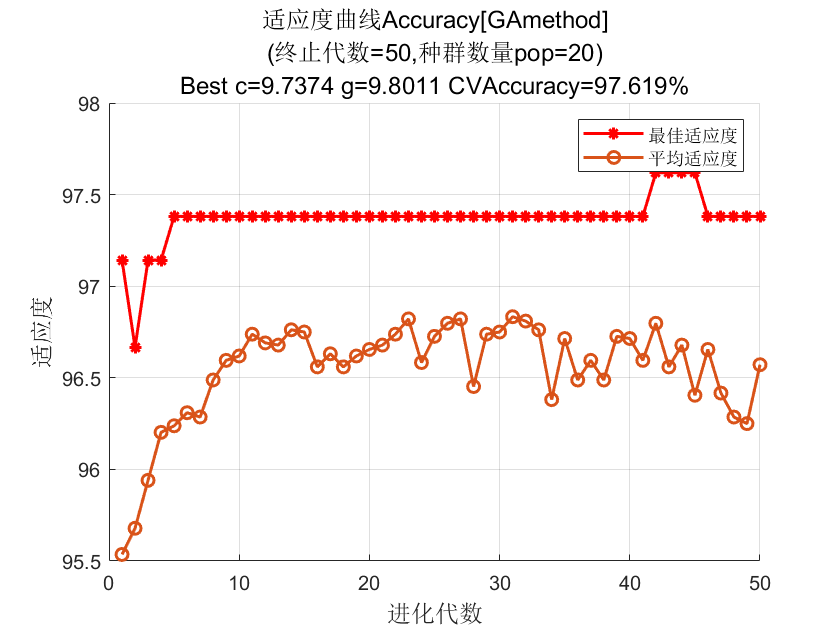

tic
[bestacc, bestc, bestg] = gaSVMcgForClass(train_label, train_data);

toc

历时 29.591709 秒。


s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 161
nu = 0.012359
obj = -11.373292, rho = 0.048076
nSV = 39, nBSV = 0
*
optimization finished, #iter = 174
nu = 0.023336
obj = -21.518857, rho = -0.148092
nSV = 38, nBSV = 1
*
optimization finished, #iter = 107
nu = 0.014981
obj = -13.785740, rho = -0.125385
nSV = 28, nBSV = 0
*
optimization finished, #iter = 175
nu = 0.027452
obj = -27.927897, rho = -0.261305
nSV = 33, nBSV = 1
*
optimization finished, #iter = 108
nu = 0.017307
obj = -15.925284, rho = -0.098584
nSV = 29, nBSV = 0
.*
optimization finished, #iter = 326
nu = 0.162289
obj = -195.471827, rho = 0.174435
nSV = 53, nBSV = 22
Total nSV = 135



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 99.2857% (417/420) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 98.324% (176/179) (classification)


valid_data = X_valid_noout(:, vsel_spa);
valid_label = y_valid_noout;

[test_pred_label, test_acc, ~]...
           = libsvmpredict(valid_label, valid_data, model);

Accuracy = 93.75% (150/160) (classification)
